# Song Quantification: Acoustic & Sequence Analysis

Author: Leila May Pascual 

Date: March 26 2023

Purpose: This script will demonstrate how a raw audio analog signal of birdsong is visualized into a spectrogram. Using the power threshold parameters, the onset/offset timing of individual units of vocalizations are extracted. Acoustic features of individual vocalizations are then quantified. Further analysis will reveal whether a relationship exists between acoustics of vocalizations and their context within a sequence of vocalizations and how this relationship evolves over the course of song learning.

Sober lab functions used in this notebook: 

- evsmooth.m

- SegmentNotes.m

- spect_from_waveform.m

- syllable_params_by_bird_leila.m

- one_syl_spectrogram_leila.m

- QuantPitchContours_leila.m

- OnesylSpecWithPitchContours_leila.m

Running the script: 

- This Matlab Live Script allows you to run individual sections of the script to generate results contained within each respective section. To run or re-run a section of the script, click the cursor anywhere inside the section you want to run and then press Ctrl+Enter. 

- The plots generated are interactive. You can click on the plot and several buttons will pop up on the upper right hand corner of the plot. You can press the buttons to pan (hand), zoom in or out (magnifying glass), and restore view (home). To zoom in only in the x-axis or y-axis, press and hold the cursor on the x or y segment you'd like to zoom in on. 

- You can also open the plot into a new window by clicking on the plot and pressing the curved arrow at the uppermost right hand corner of the plot. 

Steps Outline: 

- Take the raw audio signal from a microphone recording and tranform into a spectrogram. 

- Using spectrogram renderings of song, label individual syllables. Outputs of the external function, evsonganaly.m, include a string of syllable 'labels' and numerical vectors of 'onset' and 'offset' times. 

- Quantify the acoustic features of a manually identified branchpoint syllable. Substeps include determining the spectral parameters over which to quantify acoustics of the syllable. 

- Plot the distributions of acoustic features (e.g. pitch) for all trials of the branchpoint syllable. 

- Segregate the acoustics distributions according to sequence post-divergence (e.g. pitch distribution of branchpoint syllable 'a' when a --> b vs a --> c). Substeps include determining the indices of trials in which a -> b vs a -> c. 

- Repeat steps 1-6 for a different age when sequence transition probabilities have changed. 

- Quantify the difference in pitch distributions for branchpoint syllable. Quantify the difference in sequence transition probabilities. Correlate the changes in pitch distributions with the difference in sequence transition probabilities. 

## Step 1: Transform a raw audio signal into a spectrogram.

- Audio signal from a microphone were fed into Intan's recording system. Recording files are in 1-minute contiguous files of type '.rhd'

- Using two external functions (save_intan_as_mat and segment_into_songbouts_rhd), RHD files were converted into MAT files and song segments were extracted from the 1-minute recording files into their own songbout files. 

- the variable 'board_adc_data' contains the audio signal

### Plot the raw audio signal

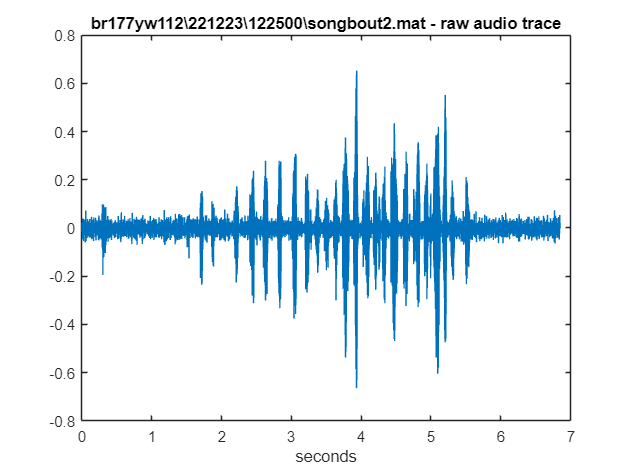

% Choose the recording file for analysis (.mat or .wav file type)
fname = 'br177yw112_221223_122500_songbout2.mat';
[~,~,ext] = fileparts(fname); % extract file extension

% Obtain the raw audio vector 
if contains('.mat', ext) % If filetype is 'mat
    load(fname, 'board_adc_data') % variable comtaining the audio signal
    sound_raw = board_adc_data;
elseif contains('.wav', ext)
    sound_raw = audioread(fname);
end

% Plot the audio trace
Fs = 30000; % recording sampling frequency in Hz (how many data points were measured per second)
tvec = (0:numel(sound_raw)-1)/Fs; % create a time vector with seconds as the unit by dividing the total number of data points by the sampling frequency
figure;
plot(tvec,sound_raw); 
title([strrep(fname,'_','\'),' - raw audio trace'])
xlabel('seconds') 

### Plot smoothed audio trace 

After plotting, explain why the two sound traces look different. What does the smoothing function do to the raw signal?

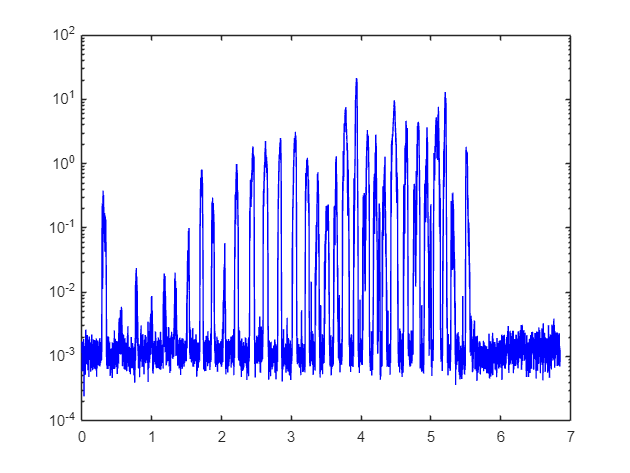

% Create smoothed sound vector with smoothing parameters:
F_low = 1000.0; % highpass frequency (Hz)
F_hi = 12000.0; % birdsong typically up to 10-12 kHz
sm_win = 2; %smoothing window (msec), intentionally oversmooth

% extract and smooth sound vector
sm=evsmooth(sound_raw,Fs,1,[],[],sm_win,F_low,F_hi); %smooth sound
sm = sm*100; % scale up smoothed sound vector
sm(1)=0.0;sm(end)=0.0;

% from evsonganaly - plot the smooth power
dsamp=10; %undersample factor for smooth display - speeds everything up
semilogy([1:length(sm(1:dsamp:end))]*dsamp/Fs,sm(1:dsamp:end),'b-')

### Find putative syllables from the smoothed audio

After generating the plot, zoom in the x-axis to inspect identified onset/offsets.

Try different thresholds (syl_thresh) for resegmenting the audio trace. 

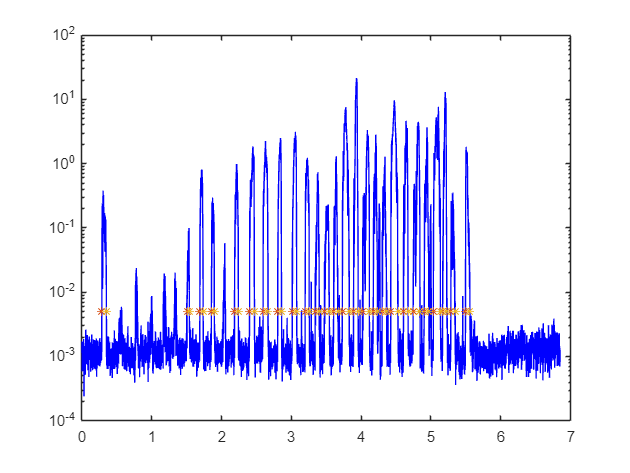

%% Extract putative syllable onsets/offsets w/ segmentation parameters:
min_int = 2; % min gap between syllables in msec
min_dur = 30; % min syllable duration in msec
syl_thresh = 0.005; % power threshold

[onsets,offsets]=SegmentNotes(sm,Fs,min_int,min_dur,syl_thresh); 

%% Plot putative syllables on top of smoothed figure
hold on
y_syl = repmat(syl_thresh,length(onsets),1);
plot(onsets,y_syl,'*'); plot(offsets,y_syl,'*'); hold off

### Transform audio signal into a spectrogram

Use external function, *spect_from_waveform*, with the arguments: (Y, FS, Plot, Spect_params).

    Y: raw waveform, FS: sampling rate Hz. Plot: 1 means to plot spectrogram

    SPECT_PARAMS: [spect_overlap spect_win_dur], i.e.

                  [percent_overlap            window_size_in_milliseconds]

                  default is [0 32]

Note: a spectrogram is a NORMALIZED calculation of the power across a determined limit of frequencies. In this case, it's 500 to 10,000 Hz. 

spect_from_waveform(sound_raw,Fs,1,[.9 16]);
clim([-16 -10])
colormap("turbo")
a=title([strrep(fname,'_','\'),' - raw audio trace']);
set(a,'fontsize',10,'fontweight','bold')

Plot the putative syllable onsets/offsets on top of the spectrogram. 

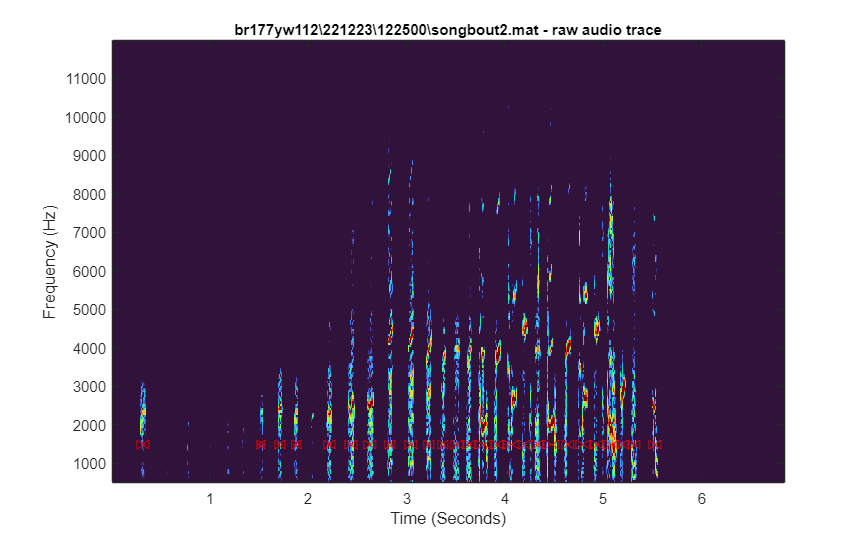

y_syl = repmat(1500,length(onsets),1);
hold on; 
plot(onsets,y_syl,'>','MarkerSize',5,'Color','r'); 
plot(offsets,y_syl,'<','MarkerSize',5,'Color','r');
set(gcf,"Position",[100 500 800 500]);

## Step 2: Labeling syllables from power threshold-based segmentation

So far, you've learned to smooth a raw waveform and used the smoothed sound waveforms to extract segments of putative syllables by imposing an amplitude threshold and other time-based criteria. 

You've also generated a spectrogram from the sound vector in order to visualize the breakdown of frequencies contained in the audio. Now we will use a GUI (graphical user interface) to assign syllable identities to those putative syllables. 

For each sound file that you've labeled, a '.not.mat' file was created that containst the character vector of syllable labels as well as vectors for 'onsets' and 'offsets' times for each syllable. The index values for onsets/'offsets vectors will correspond to the respective index values for each syllable in the 'labels' set. 

evsonganaly

## Step 2: Quantify Acoustics

Quantify the acoustics of individual syllables. The calculated acoustics will be saved in the '*.not.mat' file.

this_bird = 'br177yw112';
this_syll = 'b';
n_syl_in_sequence=1;
quant_source='notmat'; % 'notmat' (takes params from .not.mat) file or 'manual' (params from syllable_params_by_bird_leila)
%set the quantification parameters for this_syll
syllable_params_by_bird_leila(this_bird,this_syll);
% visualize how each syllable iteration is being quantified

This is for bird br177yw112
Plotting syllable b in sequence b
Acoustic parameters and quantification used: manual
Assaying at t = 50% through syllable with frequency  range [1000  2500] Hz
br177yw112_221223_100159_songbout2.mat.not.mat
Found 0 examples
br177yw112_221223_122400_songbout1.mat.not.mat
Found 6 examples
br177yw112_221223_122400_songbout2.mat.not.mat
Found 5 examples


Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted

Error in one_syl_spectrogram_leila (line 255)
                while i==0, i = waitforbuttonpress;  end

one_syl_spectrogram_leila(this_syll);
% repeat above steps until you're set on the proper syllable params

QuantPitchContours_leila(this_syll,1024,1020,1.0)

Found 0 examples of 'b' in br177yw112_221223_100159_songbout2.mat.not.mat
    {'Sampling frequency (Fs) for br177yw112_221223_100159_songbout2.matequals 30000 instead of 32000'}    {'click 'OK' to resample with ratio 16 / 15'}    {'otherwise click 'Quit' and copy files with this Fs'}    {'to a different folder to prevent crashes'}



btn = 'OK'

Found 6 examples of 'b' in br177yw112_221223_122400_songbout1.mat.not.mat
Found 5 examples of 'b' in br177yw112_221223_122400_songbout2.mat.not.mat
Found 7 examples of 'b' in br177yw112_221223_122400_songbout3.mat.not.mat
Found 2 examples of 'b' in br177yw112_221223_122500_songbout2.mat.not.mat
Found 2 examples of 'b' in br177yw112_221223_122900_songbout1.mat.not.mat
Found 3 examples of 'b' in br177yw112_221223_123700_songbout1.mat.not.mat
Found 4 examples of 'b' in br177yw112_221223_123700_songbout2.mat.not.mat
Found 5 examples of 'b' in br177yw112_221223_124100_songbout1.mat.not.mat
Found 0 examples of 'b' in br177yw112_221223_124300_songbout1.mat.not.mat
Found 4 examples of 'b' in br177yw112_221223_124700_songbout1.mat.not.mat
Found 2 examples of 'b' in br177yw112_221223_124700_songbout2.mat.not.mat
Found 2 examples of 'b' in br177yw112_221223_125000_songbout1.mat.not.mat
Found 1 examples of 'b' in br177yw112_221223_125600_songbout1.mat.not.mat
Found 5 examples of 'b' in br177yw112_

This is for bird br177yw112
Plotting syllable b in sequence b
Channel with bird's actual song is assumed to be obs0
Assaying at t = 50% through syllable with frequency  range [1000  2500] Hz
br177yw112_221223_100159_songbout2.mat.not.mat
Found 0 examples
br177yw112_221223_122400_songbout1.mat.not.mat
Found 6 examples


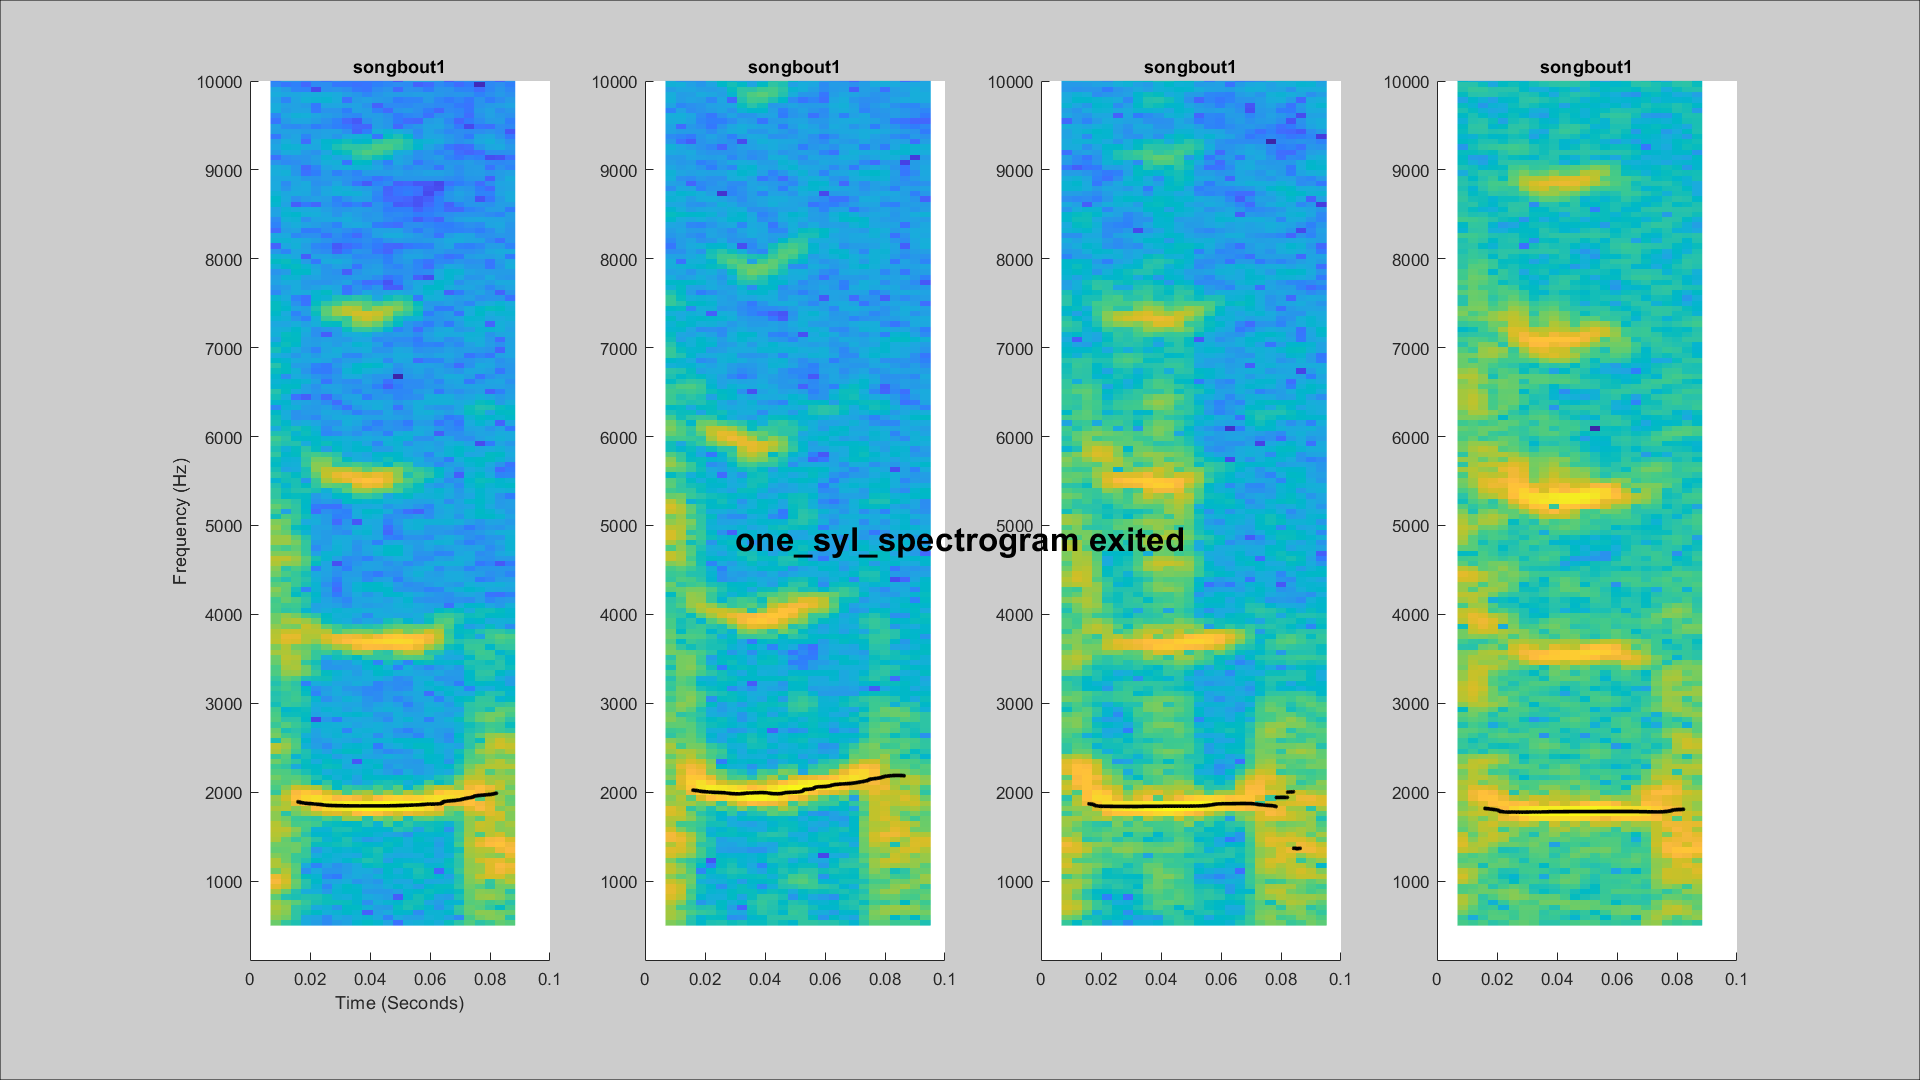

OneSylSpecWithPitchContours_leila(this_syll,1) %visualize pitch contour quantification

% quantify syllable acoustics using the syllable params above. Results are
% saved in the '.not.mat' files. Summary table of results from all files on
% this directory are saved as '__birdname__date___syl_x.mat'
quantify_acoustics(this_syll,1,'mat');

This is for bird br177yw112
Window duration = 16 msec, overlap = 0.8, assaying at t=50 with freq cutoff at [1000  2500]
Found 0 examples of 'b' in br177yw112_221223_100159_songbout2.mat.not.mat
Found 6 examples of 'b' in br177yw112_221223_122400_songbout1.mat.not.mat
Found 5 examples of 'b' in br177yw112_221223_122400_songbout2.mat.not.mat
Found 7 examples of 'b' in br177yw112_221223_122400_songbout3.mat.not.mat
Found 2 examples of 'b' in br177yw112_221223_122500_songbout2.mat.not.mat
Found 2 examples of 'b' in br177yw112_221223_122900_songbout1.mat.not.mat
Found 3 examples of 'b' in br177yw112_221223_123700_songbout1.mat.not.mat
Found 4 examples of 'b' in br177yw112_221223_123700_songbout2.mat.not.mat
Found 5 examples of 'b' in br177yw112_221223_124100_songbout1.mat.not.mat
Found 0 examples of 'b' in br177yw112_221223_124300_songbout1.mat.not.mat
Found 4 examples of 'b' in br177yw112_221223_124700_songbout1.mat.not.mat
Found 2 examples of 'b' in br177yw112_221223_124700_songbout2.mat.

## Step 3: Plot Acoustic Metrics

load('br177yw112_12_23_2022_syl_b.mat') %fill in the name of the summary file
syllable = 'b';

figure;histogram(spect_entropy,'BinWidth',0.003,'Normalization','probability')
xlabel('Spectral Entropy')
ylabel('Probability')
title([this_bird ', syllable ' syllable])

figure;histogram(weighted_avg,'BinWidth',15,'Normalization','probability')
xlabel('Weighted Pitch Average (Hz)')
ylabel('Probability')

figure;histogram(amp_at_pitchquant,'BinWidth',0.005,'Normalization','probability')
xlabel('Amplitude at pitch quantification time point')
ylabel('Probability')

figure;histogram(amp_at_pitchquant,'BinWidth',0.005,'Normalization','probability')
xlabel('Amplitude at pitch quantification time point')
ylabel('Probability')